# initial


clear;  
close all;


## xx

initialization();

MEX 配置为使用 'Microsoft Visual C++ 2019' 以进行 C++ 语言编译。
使用 'Microsoft Visual C++ 2019' 编译。
MEX 已成功完成。


## compute putative matches

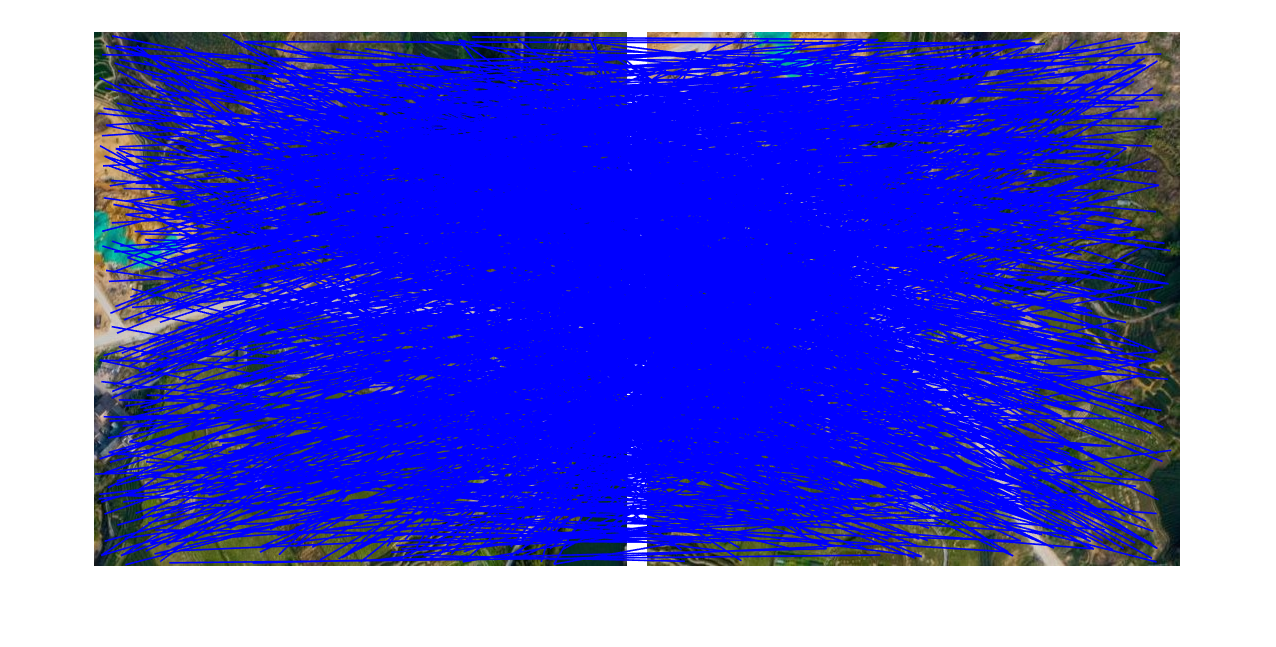


img1=imread('pair16_A.JPG');
img2=imread('pair16_B.JPG');

load pair16.mat;

P1 = P1';
P2 = P2';
X1 = P1(1,:);
Y1 = P1(2,:);
X2 = P2(1,:) + size(img1,2)+20;
Y2 = P2(2,:);

figure(1) ; clf ;
image_show = catImage(img1,img2);
imshow(image_show) ;
hold on ;
h = line([X1 ; X2], [Y1 ; Y2]) ;
set(h,'linewidth', 1, 'color', 'b') ;
hold off;


norm_P1 = P1;
norm_P2 = P2;

norm_P1(1,:) = norm_P1(1,:)/size(img1,2);
norm_P1(2,:) = norm_P1(2,:)/size(img1,1);
norm_P2(1,:) = norm_P2(1,:)/size(img2,2);
norm_P2(2,:) = norm_P2(2,:)/size(img2,1);



## input cluster result

cluster1 = HDBSCAN(norm_P1');
cluster2 = HDBSCAN(norm_P2');
   
cluster1.run_hdbscan(2,5,5,[],[]);

Training cluster hierarchy...
	Data matrix size:
		1456 points x 2 dimensions

	Min # neighbors: 2
	Min cluster size: 5
	Min # of clusters: 5
	Skipping every 0 iteration

Training took 0.943 seconds


cluster2.run_hdbscan(2,5,5,[],[]);

Training cluster hierarchy...
	Data matrix size:
		1456 points x 2 dimensions

	Min # neighbors: 2
	Min cluster size: 5
	Min # of clusters: 5
	Skipping every 0 iteration

Training took 0.849 seconds


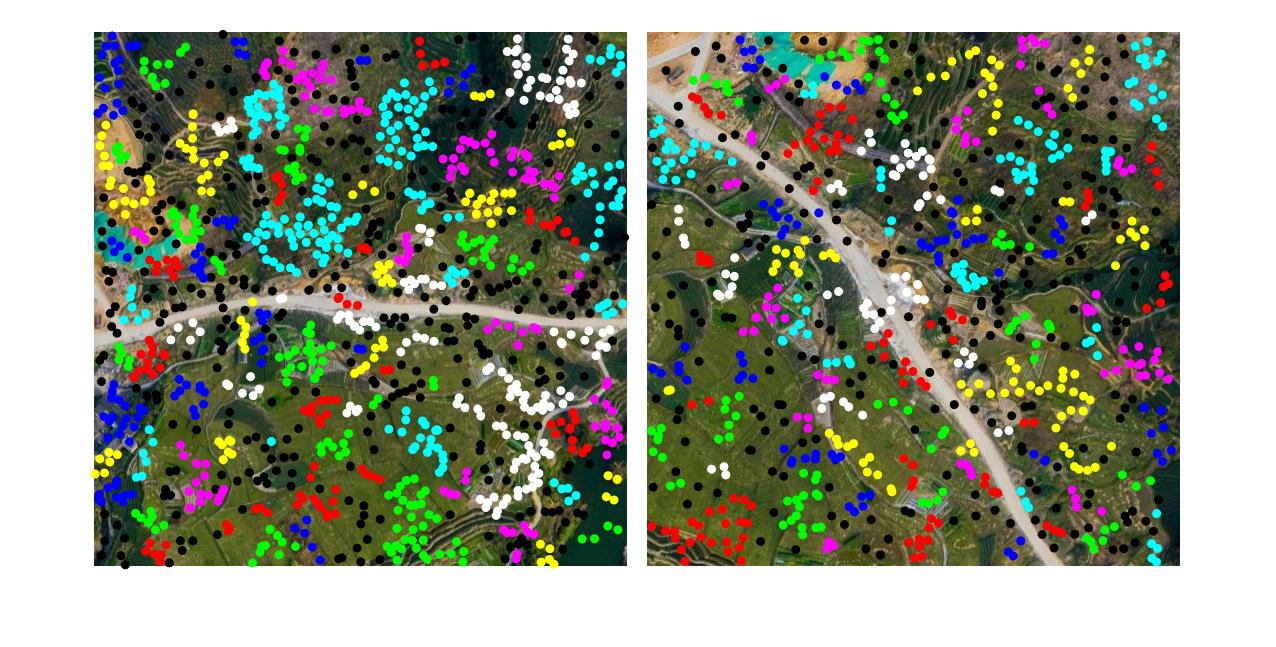


index_matches = (1:size(norm_P1,2));
cluster_1 = [index_matches', norm_P1', double(cluster1.labels)];
cluster_2 = [index_matches', norm_P2', double(cluster2.labels)];

cluster_1 = sortrows(cluster_1,4);
cluster_2 = sortrows(cluster_2,4);

drawCluster(cluster_1, cluster_2, img1, img2);

## mismatches removal


realMatches = mvMismatches(cluster_1,cluster_2, 0.8);

0.8
1456*4
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.25
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.25
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.25
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.2
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.2
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.2
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.2
0
0
0
0
0
0
0
0
0
0
0
0
0.2
0
0
0
0
0
0
0
0
0
0
0
0
0.2
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.4
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.2
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.2
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.117647
0
0
0
0.0588235
0
0
0
0
0
0
0.0588235
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0
0.0588235
0
0
0

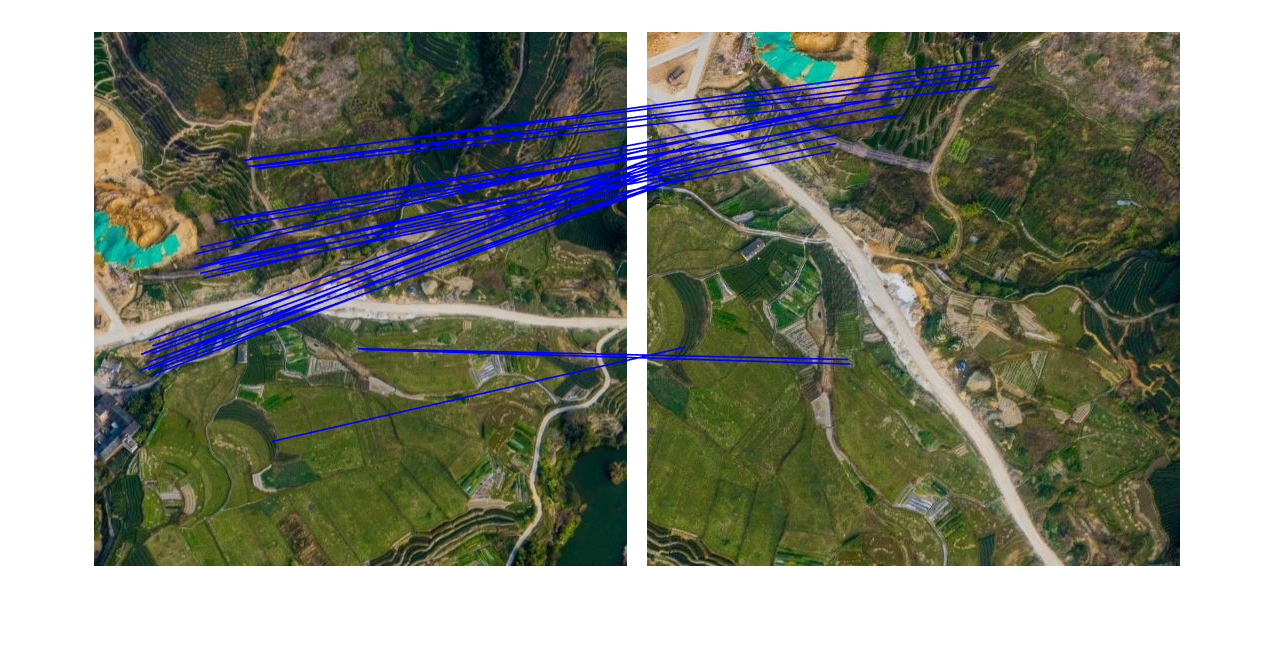


X_1 = P1(1,realMatches);
Y_1 = P1(2,realMatches);
X_2 = P2(1,realMatches) + size(img1,2)+20;
Y_2 = P2(2,realMatches);

figure(3) ; clf ;
imshow(image_show) ;
hold on ;
h = line([X_1 ; X_2], [Y_1 ; Y_2]) ;
set(h,'linewidth', 1, 'color', 'b') ;
hold off;


ComIndex = intersect(realMatches, CorrectIndex);
SuccessNum = size(ComIndex,1);
Recall = SuccessNum / size(CorrectIndex,1)

Recall = 0.0102

Precision = SuccessNum / size(realMatches,1)

Precision = 0.0952